vel35 = fit(v35.VarName1, v35.VarName2, 'rat23')
vel2 = fit(v2.VarName1, v2.VarName2, 'rat23')
vel5 = fit(v5.VarName1, v5.VarName2, 'rat23')
dedicated = fit(dout.VarName1, dout.VarName2, 'rat23')

dynamic =      General model Rat23:
     dynamic(x) = (p1*x^2 + p2*x + p3) /
               (x^3 + q1*x^2 + q2*x + q3)
     Coefficients (with 95% confidence bounds):
       p1 =  -4.468e+04  (-4.132e+08, 4.131e+08)
       p2 =   4.548e+04  (-4.205e+08, 4.206e+08)
       p3 =      -575.9  (-5.326e+06, 5.325e+06)
       q1 =        9360  (-8.655e+07, 8.657e+07)
       q2 =   5.085e+04  (-4.701e+08, 4.702e+08)
       q3 =        3138  (-2.901e+07, 2.902e+07)

dedicated =      General model Rat23:
     dedicated(x) = (p1*x^2 + p2*x + p3) /
               (x^3 + q1*x^2 + q2*x + q3)
     Coefficients (with 95% confidence bounds):
       p1 =  -2.423e+04  (-9.382e+07, 9.377e+07)
       p2 =   2.401e+04  (-9.293e+07, 9.298e+07)
       p3 =      -220.6  (-8.544e+05, 8.539e+05)
       q1 =       458.6  (-1.779e+06, 1.78e+06)
       q2 =    2.44e+04  (-9.444e+07, 9.448e+07)
       q3 =        2428  (-9.398e+06, 9.403e+06)

no_control = fit(nout.VarName1, nout.VarName2, 'rat23')

no_control =      General model Rat23:
     no_control(x) = (p1*x^2 + p2*x + p3) /
               (x^3 + q1*x^2 + q2*x + q3)
     Coefficients (with 95% confidence bounds):
       p1 =  -1.972e+04  (-9.188e+07, 9.184e+07)
       p2 =   2.101e+04  (-9.788e+07, 9.792e+07)
       p3 =        -249  (-1.16e+06, 1.16e+06)
       q1 =   2.069e+04  (-9.638e+07, 9.642e+07)
       q2 =   2.069e+04  (-9.638e+07, 9.642e+07)
       q3 =        1651  (-7.688e+06, 7.692e+06)

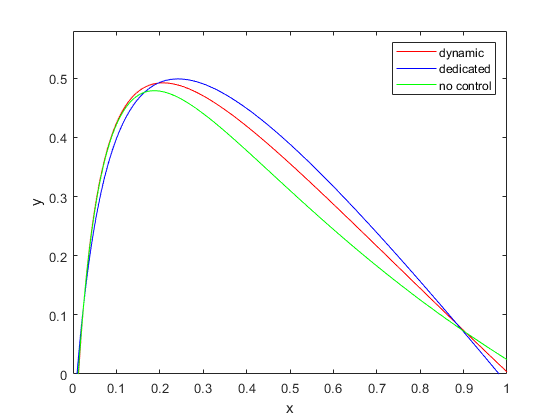

plot(vel2, 'r--');
hold on
plot(vel35, 'm');
hold on
plot(vel5, 'k');
hold on
plot(dedicated, 'b');
hold on
plot(no_control, 'g');
legend('dynamic: v < 2', 'dynamic: v < 3.5', 'dynamic: v < 5','dedicated','no control');
ylim([0,0.6]);
xlabel('density')

ylabel('flow')